# Variables

clc
close all
clear

syms theta
syms phi

l = 0.25; % 25cm
Wob = 240; % en RPM
Min = 0; %Minimum Graphique
Max = pi/3;  %Maximum du graphique



## Calculs

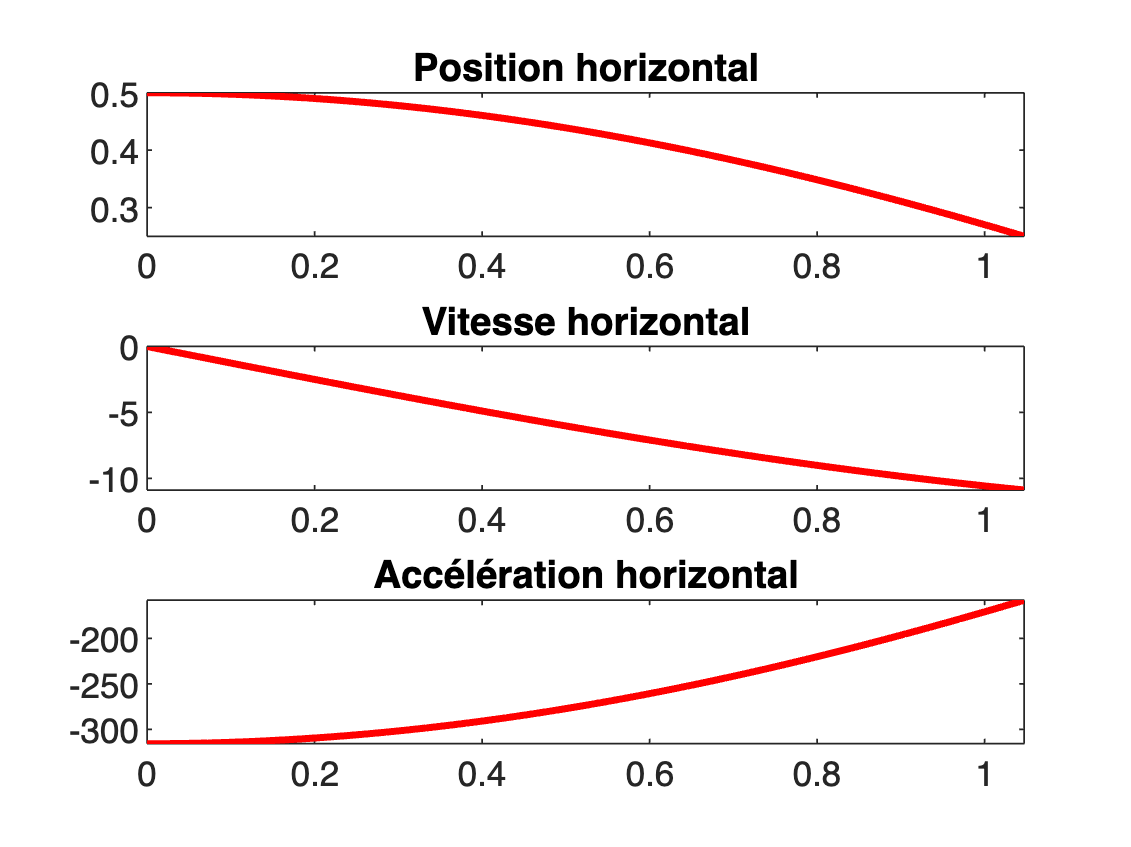


Wob = (Wob * 2 * pi) / 60;   %Transfert vers Rad/s
l1 = l;      %l1 est égale a l
l2 = l;      %l2 est égale a l

theta1 = Wob;
theta2 = 0;

phi1 = Wob;
phi2 = 0;

%Position Horizontal
Ax = 2*l1*cos(theta);

%Position Vertical
Ay = sqrt(((l1).^2) + ((l1*(sin(theta) - sqrt(1-((1-cos(theta)).^2)))).^2));

%Vitesse Horizontale
Vax = -2 * l1 * theta1 * sin(theta);

%Vitesse Vertical
Vay = l1*((theta1 * cos(theta)) + ((1-cos(theta))*sin(theta)*theta1)/sqrt(1-(1-cos(theta)).^2));

%Accélération Horizontal
Aax = -2 * (l1 * (theta1.^2) * cos(theta));

%Accélération Vertical
Aay = 0;

figure;
subplot(3, 1, 1)
fplot(Ax, [Min Max], 'Color',"red", 'LineWidth', 2)
title('Position horizontal')
hold on
subplot(3, 1, 2)
fplot(Vax, [Min Max], 'Color',"red", 'LineWidth', 2)
title('Vitesse horizontal')
hold on
subplot(3, 1, 3)
fplot(Aax, [Min Max], 'Color',"red", 'LineWidth', 2)
title('Accélération horizontal')

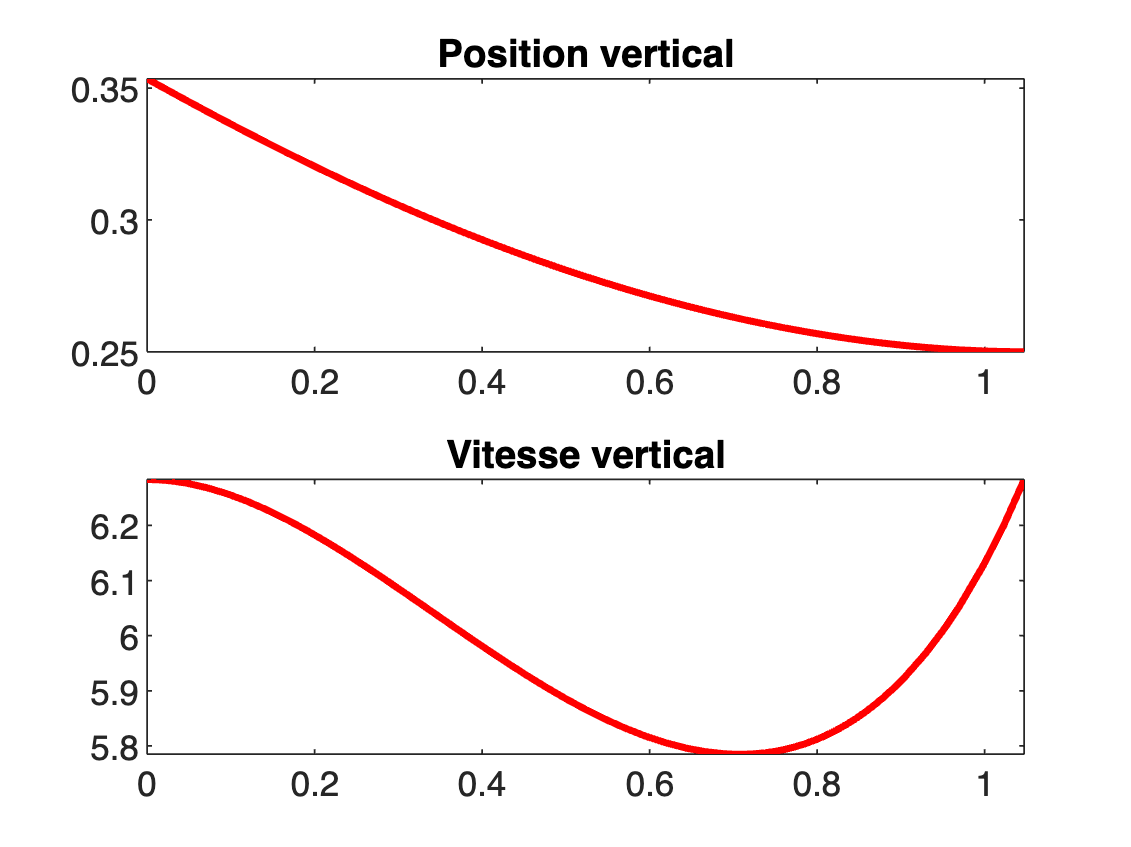


figure;
subplot(2, 1, 1)
fplot(Ay, [Min Max], 'Color',"red", 'LineWidth', 2)
title('Position vertical')
hold on
subplot(2, 1, 2)
fplot(Vay, [Min Max], 'Color',"red", 'LineWidth', 2)
title('Vitesse vertical')
hold on